clear

warning('off','all');

filepath = mfilename('fullpath');
filepath = erase(filepath,'\main');
addpath(filepath);

filepath = [filepath,'\CAD'];
addpath(filepath);

clear filepath

[robot,importInfo] = importrobot('robotic_arm.mdl');

% rodar main
% pegar tamanhos do robot do simscape -> joint HomePosition
% plot workspace
% pegar data
% rodar inverse kin

joint1 = robot.Bodies{1,1}.Joint;
joint2 = robot.Bodies{1,2}.Joint;
joint3 = robot.Bodies{1,3}.Joint;

min_angles = struct("back_servo",joint1.PositionLimits(1),...
    "front_servo",joint2.PositionLimits(1)); 
max_angles = struct("back_servo",joint1.PositionLimits(2),...
    "front_servo",joint2.PositionLimits(2));

step_size = 1; %mm
n_reachable_coordinates = length(min_angles.back_servo:step_size:max_angles.back_servo)...
    *length(min_angles.front_servo:step_size:max_angles.front_servo);

new_reachable_coordinates = zeros(2,n_reachable_coordinates);

a1 = sqrt(joint2.JointToParentTransform(1,4)^2 + joint2.JointToParentTransform(2,4)^2)*100;
a2 = sqrt(joint3.JointToParentTransform(1,4)^2 + joint3.JointToParentTransform(2,4)^2)*100;

i = 1;
for q_1 = min_angles.back_servo:step_size:max_angles.back_servo
    for q_2 = min_angles.front_servo:step_size:max_angles.front_servo        
        xEE = a1*cos(q_1) + a2*cos(q_1+q_2);
        yEE = a1*sin(q_1) + a2*sin(q_1+q_2);

        new_reachable_coordinates(:,i) = [xEE; yEE];
        i = i + 1;
    end
end

k = boundary(new_reachable_coordinates(1,:)',new_reachable_coordinates(2,:)');
workspace = [new_reachable_coordinates(1,k)' new_reachable_coordinates(2,k)']; 

clear i q_1 q_2 xEE yEE step_size n_reachable_coordinates

q1 = 0;
q2 = 0;


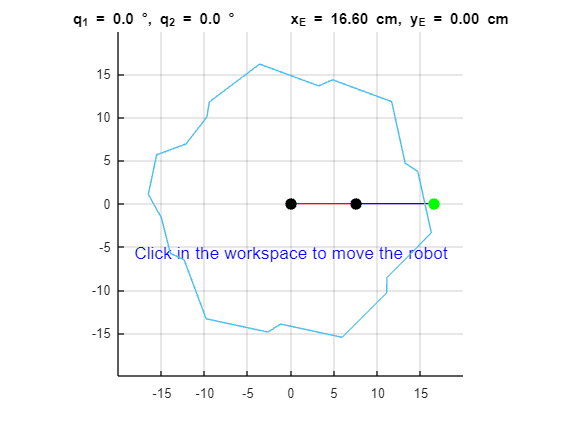

Clicked: -33.7 -25.3


figure
plotRobot(workspace,q1,q2,a1,a2)

tic;

ts_x = timeseries();
ts_y = timeseries();
while toc<=10
    currentToc = toc;
    pt = get(gca,'Position');
    fprintf('Clicked: %.1f %.1f\n', pt(1,1), pt(1,2));
    ts_x = append(ts_x,timeseries(pt(1,1),currentToc));
    ts_y = append(ts_y,timeseries(pt(1,2),currentToc));
end

Clicked: 0.1 0.1
Clicked: 0.1 0.1
Clicked: 0.1 0.1
Clicked: 0.1 0.1
Clicked: 0.1 0.1
Clicked: 0.1 0.1
Clicked: 0.1 0.1
Clicked: 0.1 0.1
Clicked: 0.1 0.1
Clicked: 0.1 0.1
Clicked: 0.1 0.1
Clicked: 0.1 0.1
Clicked: 0.1 0.1
Clicked: 0.1 0.1
Clicked: 0.1 0.1
Clicked: 0.1 0.1
Clicked: 0.1 0.1
Clicked: 0.1 0.1
Clicked: 0.1 0.1
Clicked: 0.1 0.1
Clicked: 0.1 0.1
Clicked: 0.1 0.1
Clicked: 0.1 0.1
Clicked: 0.1 0.1
Clicked: 0.1 0.1
Clicked: 0.1 0.1
Clicked: 0.1 0.1
Clicked: 0.1 0.1
Clicked: 0.1 0.1
Clicked: 0.1 0.1
Clicked: 0.1 0.1
Clicked: 0.1 0.1
Clicked: 0.1 0.1
Clicked: 0.1 0.1
Clicked: 0.1 0.1
Clicked: 0.1 0.1
Clicked: 0.1 0.1
Clicked: 0.1 0.1
Clicked: 0.1 0.1
Clicked: 0.1 0.1
Clicked: 0.1 0.1
Clicked: 0.1 0.1
Clicked: 0.1 0.1
Clicked: 0.1 0.1
Clicked: 0.1 0.1
Clicked: 0.1 0.1
Clicked: 0.1 0.1
Clicked: 0.1 0.1
Clicked: 0.1 0.1
Clicked: 0.1 0.1
Clicked: 0.1 0.1
Clicked: 0.1 0.1
Clicked: 0.1 0.1
Clicked: 0.1 0.1
Clicked: 0.1 0.1
Clicked: 0.1 0.1
Clicked: 0.1 0.1
Clicked: 0.1 0.1
Clicked: 0.1 0

function plotRobot(workspace,q1,q2,length_front,length_back)
    figure    
    hold on

    %Position of first joint 
    x_1 = length_back*cos(q1);
    y_1 = length_back*sin(q1);

    %position of the second joint
    x_EE = length_back*cos(q1) + length_front*cos(q1+q2);
    y_EE = length_back*sin(q1) + length_front*sin(q1+q2);

    %Plot first segment
    first_segment = plot([0 x_1], [0 y_1],'r');
    set(first_segment,'Tag','first_segment');
    %Plot second segment
    second_segment = plot([x_1 x_EE], [y_1 y_EE],'b');
    set(second_segment,'Tag','second_segment');

    %Plot Joints
    plot(0,0,'-o','MarkerSize',8,...
        'MarkerEdgeColor','black',...
        'MarkerFaceColor','black');
    
    endpoint_1 = plot(x_1,y_1,'-o','MarkerSize',8,...
        'MarkerEdgeColor','black',...
        'MarkerFaceColor','black');
    set(endpoint_1,'Tag','endpoint_1');

    endpoint_2 = plot(x_EE,y_EE,'-o','MarkerSize',8,...
        'MarkerEdgeColor','green',...
        'MarkerFaceColor','green');
    set(endpoint_2,'Tag','endpoint_2');

    %Plot settings
    axis equal
    grid on
    xlim(1.2*[-length_front-length_back length_front+length_back])
    ylim(1.2*[-length_front-length_back length_front+length_back])

    %Print joint angles
    caption = sprintf('q_1 = %.1f °, q_2 = %.1f °       x_E_E = %.2f cm, y_E_E = %.2f cm',...
        rad2deg(q1), rad2deg(q2), x_EE, y_EE);      
    title(caption);    
    
    %Print text
    text(0, -0.9*length_back, 'Click in the workspace to move the robot', ...
      'VerticalAlignment', 'bottom', ...
      'HorizontalAlignment', 'center','fontsize',13,'color','blue');
    
    %Plot worspace
    plot(workspace(:,1),workspace(:,2));

    pointClickCallback()
end    

function pointClickCallback()
    pt = get(gca,'CurrentPoint');
    fprintf('Clicked: %.1f %.1f\n', pt(1,1), pt(1,2));
    % setEndeffektorPosition(pt(1,1),pt(1,2)); 
end